# LKA Ensmeble Training

clear;
close all;
bdclose('all');
addpath('/home/momentumlab/Documents/git/AI-CPS-Ensemble/LKA/model')
addpath('/home/momentumlab/Documents/git/AI-CPS-Ensemble/LKA/DRL_training/trained_agent')
addpath('/home/momentumlab/Documents/git/AI-CPS-Ensemble/LKA/abstraction/')

## Environment Setup

m = 1575;   % total vehicle mass (kg)
Iz = 2875;  % yaw moment of inertia (mNs^2)
lf = 1.2;   % longitudinal distance from center of gravity to front tires (m)
lr = 1.6;   % longitudinal distance from center of gravity to rear tires (m)
Cf = 19000; % cornering stiffness of front tires (N/rad)
Cr = 33000; % cornering stiffness of rear tires (N/rad)

Vx = 15;    % longitudinal velocity (m/s)

Ts = 0.1;   % sample time
T = 15;     % simulation time

u_min = -0.5;   % maximum steering angle
u_max = 0.5;    % minimum steering angle

line_width = 3.7;   % highway lane width
avg_car_width = 2;  % average car width 
max_late_dev = (line_width-avg_car_width)/2-0.1;
max_rel_yaw_ang = 0.261799; % lateral deviation tolerence
lat_terminate_error = 1.5;

rho = 0.001;        % curvature of the road
e1_initial = 0.2;   % initial lateral deviation
e2_initial = 0.1;   % initial yaw angle

time = 0:Ts:T;
md = getCurvature(Vx,time); % previewed curvature

## Load Constitutional Controllers

% load trained RL controllers

rlAgentName = ["LKA-DDPG-16-Jun-0.8-0.2-0.05", "LKA-DDPG-17-Jun-0.2-0.8-0.05", "LKA-DDPG-17-Jun-0.5-0.5-0.05",...
                "LKA-SAC-17-Jun-0.2-0.8-0.05", "LKA-SAC-17-Jun-0.8-0.2-0.05", "LKA-SAC-17-Jun-0.5-0.5-0.05",...
                "LKA-TD3-17-Jun-0.3-0.7-0.05", "LKA-TD3-17-Jun-0.8-0.2-0.05", "LKA-TD3-17-Jun-0.5-0.5-0.05"];

agent1 = load(rlAgentName(1)).agent;
agent2 = load(rlAgentName(2)).agent;
agent3 = load(rlAgentName(3)).agent;
agent4 = load(rlAgentName(4)).agent;
agent5 = load(rlAgentName(5)).agent;
agent6 = load(rlAgentName(6)).agent;
agent7 = load(rlAgentName(7)).agent;
agent8 = load(rlAgentName(8)).agent;
agent9 = load(rlAgentName(9)).agent;

numRL = 9;      % num of RL controllers
rewardWeights = [0.5, 0.5, 0.05];  % rewardWeights for candidate agents
isTerminate = false;               % candidate agents do not terminate
predIndexVector = 3;         % only take the total reward as the prediction result

% load abstracted MDP
abstractMDP = load("LKA_abstract_model").abModel;
actionUB = abstractMDP.actionUB;
rewardUB1 = abstractMDP.rewardUB_1;
rewardUB2 = abstractMDP.rewardUB_2;
rewardToIndex = abstractMDP.rewardToIndexTable;
tranTable = abstractMDP.tranTable;

## DRL Obs/Act configuration

Creating an environment model includes action, obervation

**Observation**: 

- Leteral deviation

- Integral of leteral deviation

- Relative yaw angle

- Integral of relative yaw angle

- Derivative of lateral deviation

- Derivative of relative yaw angle

**Action**: Ego car steering anfle, [-0.5, 0.5]

% if use prediction as additional features
isPred = 0;

if isPred
% observation
    obsInfo = rlNumericSpec([15 1],...
        'LowerLimit', -inf*ones(15,1),...
        'UpperLimit', inf*ones(15,1));
    obIsnfo.Name = 'observations';
    obsInfo.Description = 'lateral deviation, yaw angle, predict reward';
    numObservations = obsInfo.Dimension(1);
else
    obsInfo = rlNumericSpec([6 1],...
        'LowerLimit', -inf*ones(6,1),...
        'UpperLimit', inf*ones(6,1));
    obIsnfo.Name = 'observations';
    obsInfo.Description = 'lateral deviation, yaw angle';
    numObservations = obsInfo.Dimension(1);
end

% action
actInfo = rlFiniteSetSpec([1 2 3 4 5 6 7 8 9]);
actInfo.Name = 'controller selection';
numActions = actInfo.Dimension(1);

mdl = 'LKA_ensemble_RL_training';
agentblk = [mdl, '/ensemble controller/ensemble_RL'];

% Build the environment interface object.
env = rlSimulinkEnv(mdl,agentblk,obsInfo,actInfo);

% Set a custom reset function that randomizes the reference values for the model.
env.ResetFcn = @(in)localResetFcn(in);

% Fix the random generator seed for reproducibility
% rng(0);

## DRL Agent Configuration

Create a network to be used as underlying critic approximator

criticNetwork = [
    featureInputLayer(numObservations,'Normalization','none','Name','observation')
    fullyConnectedLayer(32,'Name','CriticStateFC1')
    reluLayer('Name','CriticRelu1')
    fullyConnectedLayer(64,'Name','CriticStateFC2')
    reluLayer('Name','CriticCommonRelu1')
    fullyConnectedLayer(128,'Name','CriticCommonFC1')
    reluLayer('Name','CriticCommonRelu2')
    fullyConnectedLayer(64,'Name','CriticCommonFC2')
    reluLayer('Name','CriticCommonRelu3')
    fullyConnectedLayer(32,'Name','CriticCommonFC3')
    reluLayer('Name','CriticCommonRelu4')
    fullyConnectedLayer(1,'Name','CriticOutput')];

% convert the network to a dlnetwork object
criticNetwork = dlnetwork(criticNetwork);

% create critic based on the network approximator
critic = rlValueFunction(criticNetwork,obsInfo,'UseDevice','cpu');

% create a network to be used as underlying actor approximator
actorNetwork = [
    featureInputLayer(prod(obsInfo.Dimension),'Normalization','none','Name','observation')
    fullyConnectedLayer(64,'Name','ActorFC1')
    reluLayer('Name','ActorRelu1')
    fullyConnectedLayer(128,'Name','ActorFC2')
    reluLayer('Name','ActorRelu2')
    fullyConnectedLayer(length(actInfo.Elements),'Name','ActorFC3')                       
    softmaxLayer('Name','actionProb')];

actor  = rlDiscreteCategoricalActor(actorNetwork,obsInfo,actInfo);

**Noise model:**

- It is common to set `StandardDeviation*sqrt(Ts)` to a value between 1% and 10% of your action rang.

- To increase exploration, you can reduce the `StandardDeviationDecayRate`.

% Optimization options for actors and critics
myCriticOpts=rlOptimizerOptions(...
    'LearnRate',1e-4,...
    'GradientThreshold',1,...
    'GradientThresholdMethod',"l2norm",...
    'L2RegularizationFactor', 1e-4,...
    'Optimizer',"adam");

myActorOpts=rlOptimizerOptions(...
    'LearnRate',1e-4,...
    'GradientThreshold',1,...
    'GradientThresholdMethod',"l2norm",...
    'L2RegularizationFactor', 1e-4,...
    'Optimizer',"adam");

agentOptions = rlACAgentOptions(...
    'CriticOptimizerOptions', myCriticOpts,...
    'ActorOptimizerOptions',myActorOpts,...
    'SampleTime',Ts,...
    'NumStepsToLookAhead',5,...
    'EntropyLossWeight',0.01,...
    'DiscountFactor',0.99);

% agent creation
agentEnsemble = rlACAgent(actor, critic, agentOptions);

## **Training Configurations**

Change the weights distribution among subsitutional rewards

maxepisodes = 5000; 
maxsteps = ceil(T/Ts);
window_length = 20;

stateTable = tranTable(:,1);
actionTable = tranTable(:,2);

% change reward weights distribution
ensembleRewardWeights = [0.5, 0.5, 0.05];

trainOpts = rlTrainingOptions(...
    'MaxEpisodes', maxepisodes, ...
    'MaxStepsPerEpisode', maxsteps, ...
    'ScoreAveragingWindowLength',window_length, ...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue', 1.1*sum(ensembleRewardWeights)*maxsteps*0.95,...
    'Verbose', false,...
    'Plots','training-progress',...
    'UseParallel',false);

doTraining = true;

if doTraining
    % Train the agent.
    isEnsembleTerminate = true;
    trainingStats = train(agentEnsemble,env,trainOpts);
else
%     agent = load('preTrainedAgent.mat');
%     agent = agent.agent;
end

## Save trained agent 

Save DRL agent with training configurations, agent configurations and training progress info

isSave = true;

if isSave
    dateOfTrain = date;
    if isPred
        agentName = ['LKA-ensemble-pred--AC-9-RL-0-MPC-', dateOfTrain(1:end-5)];
    else
        agentName = ['LKA-ensemble-no-pred--AC-9-RL-0-MPC-', dateOfTrain(1:end-5)];
    end
    agentName = agentName+...
        "-"+string(ensembleRewardWeights(1))+...
        "-"+string(ensembleRewardWeights(2))+...
        "-"+string(ensembleRewardWeights(3));

    saveAgent = struct('agentName', agentName, ...
                 'agent', agentEnsemble, ...
                 'rewardWeights', ensembleRewardWeights, ...
                 'ensembleMPC',[],...
                 'agentOptions', agentOptions, ...
                 'criticNetwork', criticNetwork, ...
                 'actorNetwork', actorNetwork, ...
                 'trainOpts', trainOpts);

    path = "/home/momentumlab/Documents/git/AI-CPS-Ensemble/LKA/ensemble/trained_agent/";
    save(path+agentName+'.mat', "saveAgent");
    disp(agentName + ' saved')
end

LKA-ensemble-no-pred--AC-9-RL-0-MPC-24-Jun-0.5-0.5-0.05 saved


## Simulation & plotting

simOpts = rlSimulationOptions('MaxSteps',maxsteps,'StopOnError','on');
% get results
experiences = sim(env,agentEnsemble,simOpts);
totalReward = sum(experiences.Reward);

% extract signals from simulation results
time = experiences.SimulationInfo.tout;
steps = size(time);
steps = steps(1);
lateral_deviation = experiences.SimulationInfo.logsout.getElement('lat_error').Values.Data;
relative_yaw_angle =  experiences.SimulationInfo.logsout.getElement('yaw_error').Values.Data;
RL_steer_angle =  experiences.SimulationInfo.logsout.getElement('steering_angle').Values.Data;
RL_steer_angle = reshape(RL_steer_angle, [steps,1]);
selection = experiences.SimulationInfo.logsout.getElement('selection').Values.Data;
selection = reshape(selection, [steps,1]);
velocity =  experiences.SimulationInfo.logsout.getElement('Vx').Values.Data;
velocity = velocity(1);

## Simulation & Plotting

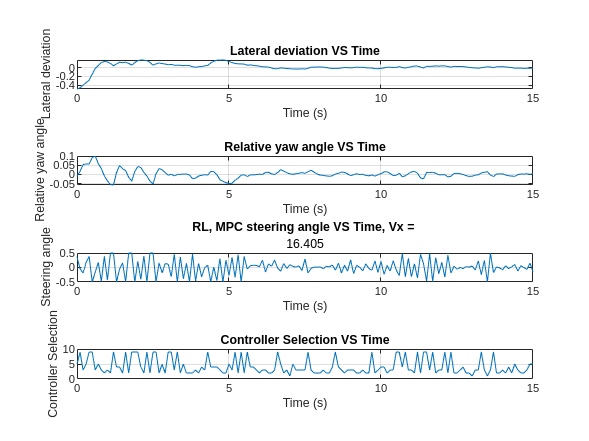

figure(1);
subplot(4,1,1)
plot(time,lateral_deviation)
title('Lateral deviation VS Time')
xlabel('Time (s)') 
ylabel('Lateral deviation') 
grid on

subplot(4,1,2)
plot(time,relative_yaw_angle)
title('Relative yaw angle VS Time')
xlabel('Time (s)') 
ylabel('Relative yaw angle') 
grid on

subplot(4,1,3)
plot(time,RL_steer_angle)
title('RL, MPC steering angle VS Time, Vx = ',velocity)
% legend('RL', 'MPC')
xlabel('Time (s)') 
ylabel('Steering angle') 
grid on

subplot(4,1,4)
plot(time,selection)
title('Controller Selection VS Time')
xlabel('Time (s)') 
ylabel('Controller Selection') 
grid on

## Training progress info

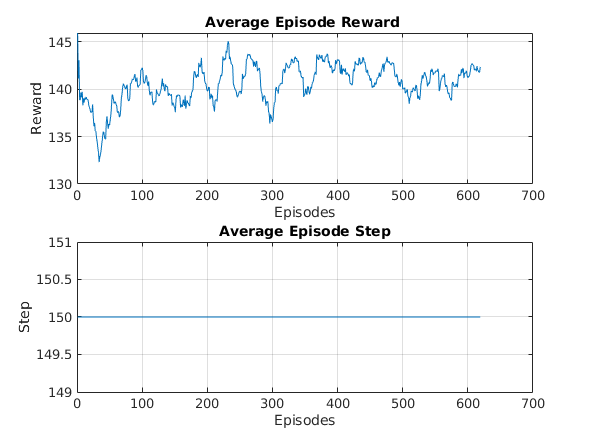

episodes = trainingStats.EpisodeIndex;
episode_reward = trainingStats.EpisodeReward;
episode_step = trainingStats.EpisodeSteps;
episode_avg_reward = trainingStats.AverageReward;
episode_avg_step = trainingStats.AverageSteps;

figure(2);
subplot(2,1,1)
plot(episodes,episode_avg_reward)
title('Average Episode Reward ')
xlabel('Episodes') 
ylabel('Reward') 
grid on

subplot(2,1,2)
plot(episodes,episode_avg_step)
title('Average Episode Step')
xlabel('Episodes') 
ylabel('Step') 
grid on

## Reset function

Generate random initial conditions:

- Initial lateral deviation: [-0.5, 0.5]

- Initial relative yaw angle: [-0.1, 0.1]

- Initial velocity: [10, 25]

function in = localResetFcn(in)
    % reset
    in = setVariable(in,'e1_initial', 0.6*(-1+2*rand)); % random value for lateral deviation
    in = setVariable(in,'e2_initial', 0.2*(-1+2*rand)); % random value for relative yaw angle
    in = setVariable(in,'Vx', 10+15*rand);              % random value for longitudinal velocity
end